## Robot Visualizer Example: Maps and Lidar

Copyright 2018 The MathWorks, Inc.

Create a map without trajectory display. The map should be a valid [`robotics.OccupancyGrid`](matlab: doc robotics.OccupancyGrid) or [`robotics.BinaryOccupancyGrid`](matlab: doc robotics.BinaryOccupancyGrid) object.

viz = Visualizer2D;
viz.showTrajectory = false;
load exampleMap
viz.mapName = 'map'

viz =   Visualizer2D with properties:

       robotRadius: 0
           mapName: 'map'
    showTrajectory: false
      hasWaypoints: false
          hasLidar: false
    hasObjDetector: false

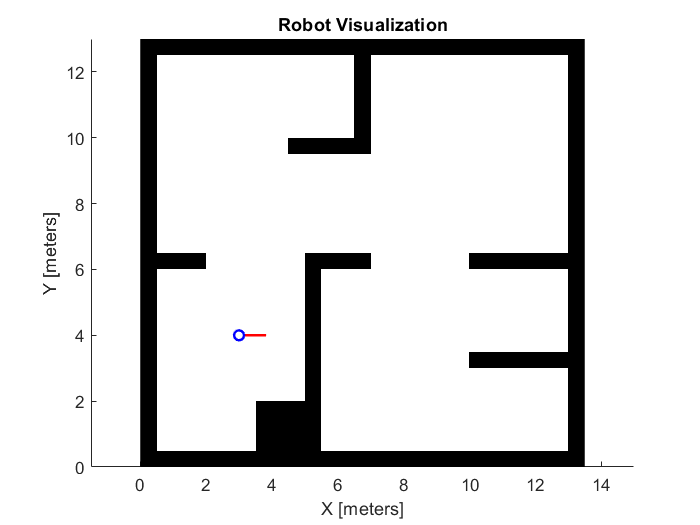

pose = [3; 4; 0];
viz(pose)

Create a [`LidarSensor`](matlab: matlab: edit mrsDocLidarSensor) object and attach it to the map. You can either set the `hasLidar `property to `true` and add corresponding range sensor parameters, or use the `attachLidarSensor` function.

release(viz); % Needed to change hasLidar property after visualizing
lidar = LidarSensor;
lidar.scanAngles = linspace(-pi/2,pi/2,7);
attachLidarSensor(viz,lidar);

Spin the robot in place, simulate the lidar sensor, and view the results.

**NOTE:** If you run this section in a plain code script, this section will be animated.

for idx = 1:10
    pose = pose + [0; 0; pi/8];
    ranges = lidar(pose);
    viz(pose,ranges)
    pause(0.25)
end